clear

% Load point clouds
Rot_init = axang2rotm([1 .33 0.74 pi/4]);
p_init = [1,-2,3]

p_init =      1    -2     3


points = [rand(1,50)'*10,rand(1,50)'*10,rand(1,50)'*10];
ptCloud1 = pointCloud(points);
ptCloud1.Color = "red"

ptCloud1 =   pointCloud with properties:

     Location: [50×3 double]
        Count: 50
      XLimits: [0.023679 9.8074]
      YLimits: [0.53652 9.9827]
      ZLimits: [0.43871 9.9535]
        Color: [50×3 uint8]
       Normal: []
    Intensity: []


ptCloud2 = pointCloud(points*Rot_init + p_init);
ptCloud2.Color = "blue"

ptCloud2 =   pointCloud with properties:

     Location: [50×3 double]
        Count: 50
      XLimits: [1.5008 13.431]
      YLimits: [-3.0181 9.4566]
      ZLimits: [-0.37039 12.618]
        Color: [50×3 uint8]
       Normal: []
    Intensity: []



% Initialize plot
figure;
subplot(2,1,1)
h1 = scatter3(ptCloud1.Location(:,1), ptCloud1.Location(:,2), ptCloud1.Location(:,3));

hold on;
h2 = scatter3(ptCloud2.Location(:,1), ptCloud2.Location(:,2), ptCloud2.Location(:,3), "x");

title('ICP Registration');
legend('Point Cloud 1', 'Point Cloud 2');

maxIterations = 100;
rmse_target = 1e-1;
T = eye(4);
for i = 1:maxIterations
    % Find nearest neighbors
    [idx, dist] = findClosestPoint(ptCloud1.Location, ptCloud2.Location);
    
    % Estimate transformation
    
    [R, p] = T_SVD(ptCloud1.Location, ptCloud2.Location(idx,:));
    Tnew = eye(4);
    Tnew(1:3,1:3) = R;
    Tnew(1:3,4) = p;
    
%     Update transformation
    T = Tnew * T;
    ptCloud1 = pctransform(ptCloud1, rigidtform3d(R,p));
    
    % Compute error
    error = computeError(ptCloud1.Location, ptCloud2.Location);

    
    % Plot intermediate results
    set(h1, 'XData', ptCloud1.Location(:,1), 'YData', ptCloud1.Location(:,2), 'ZData', ptCloud1.Location(:,3));
    title(sprintf('ICP Registration (Iteration %d)\nError: %f', i, error));
    drawnow;
    
    % Check convergence
    if error < rmse_target
        disp("Convergence Reached")
        break
    end
end

Convergence Reached


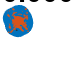


% Plot final result
set(h1, 'XData', ptCloud1.Location(:,1), 'YData', ptCloud1.Location(:,2), 'ZData', ptCloud1.Location(:,3));
title(sprintf('ICP Registration (Iteration %d)\nError: %f', i, error));

drawnow

% function [dist_index, dist_list] = findNearestNeighbors(ptCloud1, ptCloud2)
%     % Find nearest neighbors between two point clouds using KD-tree
%     tree = KDTreeSearcher(ptCloud2);
%     [dist_index, dist_list] = knnsearch(tree, ptCloud1);
% %------------------------------------------------------------------
% % function [dist_index, dist_list] = findNearestNeighbors(points_a, points_b)
% % dist_index = zeros(length(points_a), 1);
% % dist_list = zeros(length(points_a), 1);
% % for i = 1:length(points_a)
% %     shortest_distance = 100;
% %     a_i = points_a(i)';
% %     for j = 1:length(points_b) %for each sample point
% %           b_i = points_b(j)';
% %              dist = (norm(a_i - b_i));
% %         if dist < shortest_distance
% %             shortest_distance = dist;
% %             short_dist_index = j;
% %             dist_index(i) = short_dist_index';
% %               dist_list(i) = shortest_distance';
% %         end
% %     end
% %     
% % end
% end


function [dist_index, dist_list] = findClosestPoint(points_a, points_b)
    dist_matrix = pdist2(points_a, points_b);
    [dist_list, dist_index] = min(dist_matrix, [], 2);
end



function [R, t] = T_SVD(ptCloud1, ptCloud2)
% Estimate rigid transform using SVD
X = ptCloud1;
Y = ptCloud2;
X_bar = mean(X);
Y_bar = mean(Y);
X_tilde = X - X_bar;
Y_tilde = Y - Y_bar;
H = (X_tilde' * Y_tilde)/(size(X, 1) - 1);
[U, ~, V] = svd(H); %U and V should be 3x3 matrices

tolerance = 1e-6;
R = V*U';

t = Y_bar' - R * X_bar';
end


function distance = computeError(ptCloud1, ptCloud2)
D = pdist2(ptCloud1,ptCloud2);
distance = mean(min(D,[],2))+mean(min(D,[],1));
end